% List of test files (Healthy + Anomalous)
allAudioFiles = [audioFiles, abnormalaudioFiles]; % Combine normal and test sets
numTotalFiles = length(allAudioFiles);

% Feature Storage
allFeatures = [];
allLabels = [];

for i = 1:numTotalFiles
    fileName = allAudioFiles(i);

    % Extract Features
    timeFreqFeatures = generateAudioFeatures(fileName, 1); % Extract time/freq features
    fftFeatures = generateFFTFeatures(fileName, 1, 1024);  % Extract FFT features
    
    % Convert tables to arrays and concatenate
    featureVector = [table2array(timeFreqFeatures), table2array(fftFeatures)];
    
    % Store Features
    allFeatures = [allFeatures; featureVector];
    
    % Assign Labels: Healthy (0) for waveformData, Anomalous (1) for testwaveformData
    if ismember(fileName, audioFiles)
        allLabels = [allLabels; 0]; % Healthy
    else
        allLabels = [allLabels; 1]; % Anomalous
    end
end

% Convert to Table
featureNames = [timeFreqFeatures.Properties.VariableNames, fftFeatures.Properties.VariableNames];
featureTable = array2table(allFeatures, 'VariableNames', featureNames);
featureTable.Label = allLabels;
disp(featureTable);

      RMS       ZeroCrossRate    SpectralCentroid     MFCC1      MFCC2      MFCC3       MFCC4         MFCC5        MFCC6        MFCC7         MFCC8         MFCC9        MFCC10        MFCC11        MFCC12        MFCC13        MFCC14      MaxFreqMag    MeanFreqMag    MedianFreqMag    DominantFreq    Label
    ________    _____________    ________________    _______    _______    _______    __________    _________    _________    __________    ___


% Convert features to a numeric matrix
featureMatrix = table2array(featureTable(:, 1:end-1));
labels = featureTable.Label;

% Split Data (70% Train, 30% Test)
cv = cvpartition(labels, 'HoldOut', 0.3);
XTrain = featureMatrix(training(cv), :);
YTrain = labels(training(cv));
XTest = featureMatrix(test(cv), :);
YTest = labels(test(cv));

% Train SVM Model
svmModel = fitcsvm(XTrain, YTrain, 'KernelFunction', 'linear', 'Standardize', true);

% Predict on Test Data
YPred = predict(svmModel, XTest);

% Accuracy
accuracy = sum(YPred == YTest) / length(YTest);
fprintf('SVM Accuracy: %.2f%%\n', accuracy * 100);

SVM Accuracy: 94.44%


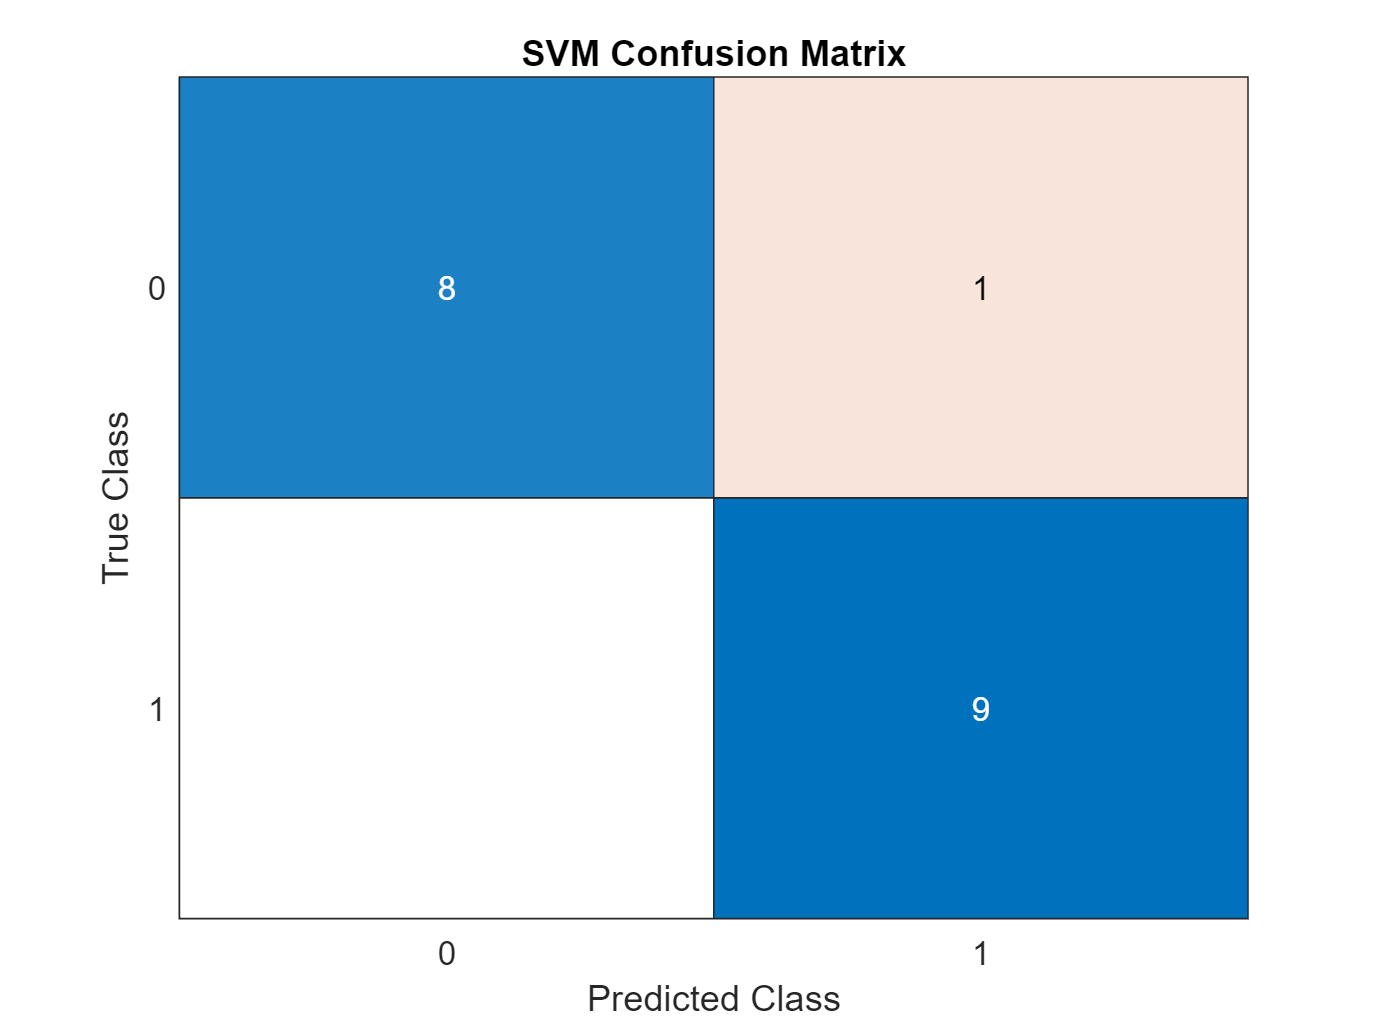


% Confusion Matrix
confusionchart(YTest, YPred);
title('SVM Confusion Matrix');